### Offset Correction vs No Correction

clear all; close all; clc;

torrespana = [40.42057,-3.664179,600];
ell = referenceEllipsoid('WGS84');

% No correction no LTE
load('/home/ygglc/desktop/phd/research/localization/core/localization-tdoa/matlab/sensys/madrid2/s6/mdphase_i1_c0_l0.mat')
dphase_1_0_0.lls = error_lls;
dphase_1_0_0.nlls = error_nlls;
[dphase_1_0_0.F_lls, dphase_1_0_0.X_lls] = ecdf(error_lls);
[dphase_1_0_0.F_nlls, dphase_1_0_0.X_nlls] = ecdf(error_nlls);

zurich_results = array2table(lls,'VariableNames',{'Latitude','Longitude'});
writetable(zurich_results,'/tmp/madridorig.csv');

% Correction no LTE
load('/home/ygglc/desktop/phd/research/localization/core/localization-tdoa/matlab/sensys/madrid2/s6/mdphase_i1_c1_l0.mat')
dphase_1_1_0.lls = error_lls;
dphase_1_1_0.nlls = error_nlls;
[dphase_1_1_0.F_lls, dphase_1_1_0.X_lls] = ecdf(error_lls);
[dphase_1_1_0.F_nlls, dphase_1_1_0.X_nlls] = ecdf(error_nlls);

zurich_results = array2table(lls,'VariableNames',{'Latitude','Longitude'});
writetable(zurich_results,'/tmp/madridmean.csv');

% Correction with LTE
load('/home/ygglc/desktop/phd/research/localization/core/localization-tdoa/matlab/sensys/madrid2/s6/mdphase_i1_c1_l1.mat')
dphase_1_1_1.lls = error_lls;
dphase_1_1_1.nlls = error_nlls;
[dphase_1_1_1.F_lls, dphase_1_1_1.X_lls] = ecdf(error_lls);
[dphase_1_1_1.F_nlls, dphase_1_1_1.X_nlls] = ecdf(error_nlls);
offset = mean(nlls(:,1:2),1) - torrespana(1:2);
offset = 0;
nlls_corr = nlls(:,1:2) - offset;
error_nlls_corr = distance(nlls_corr(:,1)',nlls_corr(:,2)',torrespana(1), torrespana(2), ell);
[mp_111_y, mp_111_x] = ecdf(error_nlls_corr);

zurich_results = array2table(nlls_corr,'VariableNames',{'Latitude','Longitude'});
writetable(zurich_results,'/tmp/madridfoc.csv');

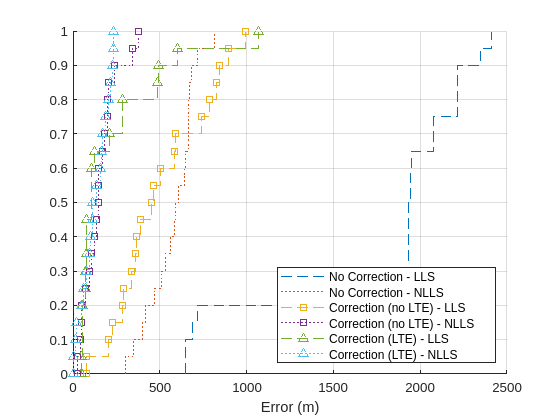

% Plotting
figure(); hold on; grid on;
stairs(dphase_1_0_0.X_lls, dphase_1_0_0.F_lls, '--');
stairs(dphase_1_0_0.X_nlls, dphase_1_0_0.F_nlls, ':');
stairs(dphase_1_1_0.X_lls, dphase_1_1_0.F_lls, '--s');
stairs(dphase_1_1_0.X_nlls, dphase_1_1_0.F_nlls, ':s');
stairs(dphase_1_1_1.X_lls, dphase_1_1_1.F_lls, '--^');
stairs(dphase_1_1_1.X_nlls, dphase_1_1_1.F_nlls, ':^');
legend('No Correction - LLS', 'No Correction - NLLS', 'Correction (no LTE) - LLS', 'Correction (no LTE) - NLLS', 'Correction (LTE) - LLS', 'Correction (LTE) - NLLS','Location','southeast');
xlabel('Error (m)');

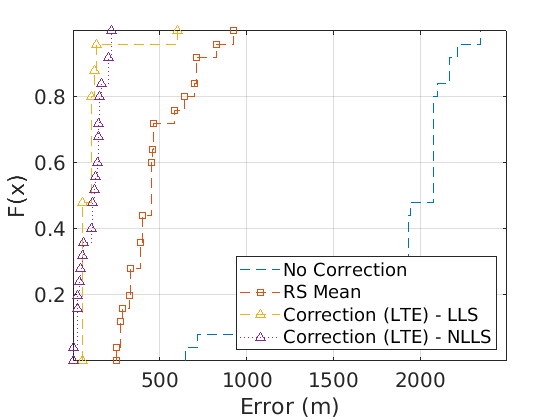

% Plotting
figure(); hold on; grid on; 
stairs(dphase_1_0_0.X_lls, dphase_1_0_0.F_lls, '--');
stairs(dphase_1_1_0.X_lls, dphase_1_1_0.F_lls, '--s');
stairs(dphase_1_1_1.X_lls, dphase_1_1_1.F_lls, '--^');
stairs(mp_111_x, mp_111_y, ':^');
legend('No Correction', 'RS Mean', 'Correction (LTE) - LLS', 'Correction (LTE) - NLLS','Location','southeast');
xlabel('Error (m)');
xticks([500,1000,1500,2000]); 
ylabel('F(x)');
yticks([0.2,0.4,0.6,0.8]);
box on; 
set(gca,'FontSize',15);

### Interpolation vs No Interpolation

% Interp 1
load('/home/ygglc/desktop/phd/research/localization/core/localization-tdoa/matlab/sensys/madrid2/s6/mdphase_i1_c1_l1_mp.mat')
dphase_1_1_1.lls = error_lls;
dphase_1_1_1.nlls = error_nlls;
[dphase_1_1_1.F_lls, dphase_1_1_1.X_lls] = ecdf(error_lls);
[dphase_1_1_1.F_nlls, dphase_1_1_1.X_nlls] = ecdf(error_nlls);
offset = 0;
% offset = mean(nlls(:,1:2),1) - torrespana(1:2);
nlls_corr = nlls(:,1:2) - offset;
error_nlls_corr = distance(nlls_corr(:,1)',nlls_corr(:,2)',torrespana(1), torrespana(2), ell);
[mp_y, mp_x] = ecdf(error_nlls_corr);

% Interp 5
load('/home/ygglc/desktop/phd/research/localization/core/localization-tdoa/matlab/sensys/madrid2/s6/mdphase_i5_c1_l1_mp.mat')
dphase_5_1_1.lls = error_lls;
dphase_5_1_1.nlls = error_nlls;
[dphase_5_1_1.F_lls, dphase_5_1_1.X_lls] = ecdf(error_lls);
[dphase_5_1_1.F_nlls, dphase_5_1_1.X_nlls] = ecdf(error_nlls);
offset = mean(nlls(:,1:2),1) - torrespana(1:2);
nlls_corr = nlls(:,1:2) - offset;
error_nlls_corr = distance(nlls_corr(:,1)',nlls_corr(:,2)',torrespana(1), torrespana(2), ell);
[mp_5_y, mp_5_x] = ecdf(error_nlls_corr);

% Interp 10
load('/home/ygglc/desktop/phd/research/localization/core/localization-tdoa/matlab/sensys/madrid2/s6/mdphase_i10_c1_l1_mp.mat')
dphase_10_1_1.lls = error_lls;
dphase_10_1_1.nlls = error_nlls;
[dphase_10_1_1.F_lls, dphase_10_1_1.X_lls] = ecdf(error_lls);
[dphase_10_1_1.F_nlls, dphase_10_1_1.X_nlls] = ecdf(error_nlls);
offset = mean(nlls(:,1:2),1) - torrespana(1:2);
nlls_corr = nlls(:,1:2) - offset;
error_nlls_corr = distance(nlls_corr(:,1)',nlls_corr(:,2)',torrespana(1), torrespana(2), ell);
[mp_10_y, mp_10_x] = ecdf(error_nlls_corr);

% Interp 20
% Correction with LTE
load('/home/ygglc/desktop/phd/research/localization/core/localization-tdoa/matlab/sensys/madrid2/s6/mdphase_i20_c1_l1_mp.mat')
dphase_20_1_1.lls = error_lls;
dphase_20_1_1.nlls = error_nlls;
[dphase_20_1_1.F_lls, dphase_20_1_1.X_lls] = ecdf(error_lls);
[dphase_20_1_1.F_nlls, dphase_20_1_1.X_nlls] = ecdf(error_nlls);
offset = mean(nlls(:,1:2),1) - torrespana(1:2);
nlls_corr = nlls(:,1:2) - offset;
error_nlls_corr = distance(nlls_corr(:,1)',nlls_corr(:,2)',torrespana(1), torrespana(2), ell);
[mp_20_y, mp_20_x] = ecdf(error_nlls_corr);
zurich_results = array2table(nlls_corr,'VariableNames',{'Latitude','Longitude'});
writetable(zurich_results,'/tmp/madrid20.csv');

% % Interp 50
% % Correction with LTE
% load('/home/ygglc/desktop/phd/research/localization/core/localization-tdoa/matlab/sensys/madrid2/s6/mdphase_i50_c1_l1_mp.mat')
% dphase_50_1_1.lls = error_lls;
% dphase_50_1_1.nlls = error_nlls;
% [dphase_50_1_1.F_lls, dphase_50_1_1.X_lls] = ecdf(error_lls);
% [dphase_50_1_1.F_nlls, dphase_50_1_1.X_nlls] = ecdf(error_nlls);

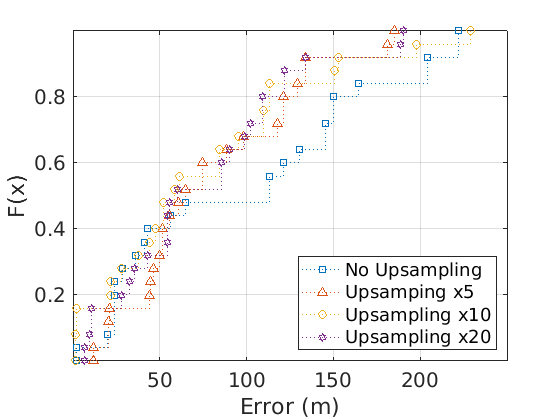

% Plotting
figure(); hold on; grid on;
stairs(mp_x, mp_y, ':s');
stairs(mp_5_x, mp_5_y, ':^');
stairs(mp_10_x, mp_10_y, ':o');
stairs(mp_20_x, mp_20_y, ':h');
legend('No Upsampling', 'Upsamping x5', 'Upsampling x10', 'Upsampling x20','Location','southeast');
xlabel('Error (m)');
xlim([0,250]);
xticks([50,100,150,200]); 
ylabel('F(x)');
yticks([0.2,0.4,0.6,0.8]);
box on; 
set(gca,'FontSize',15);

### abs/dphase/iq

% abs
load('/home/ygglc/desktop/phd/research/localization/core/localization-tdoa/matlab/sensys/madrid2/s6/mabs_i20_c1_l1.mat')
abs_1_1_1.lls = error_lls;
abs_1_1_1.nlls = error_nlls;
[abs_1_1_1.F_lls, abs_1_1_1.X_lls] = ecdf(error_lls);
[abs_1_1_1.F_nlls, abs_1_1_1.X_nlls] = ecdf(error_nlls);

% dphase
load('/home/ygglc/desktop/phd/research/localization/core/localization-tdoa/matlab/sensys/madrid2/s6/mdphase_i20_c1_l1.mat')
dphase_1_1_1.lls = error_lls;
dphase_1_1_1.nlls = error_nlls;
[dphase_1_1_1.F_lls, dphase_1_1_1.X_lls] = ecdf(error_lls);
[dphase_1_1_1.F_nlls, dphase_1_1_1.X_nlls] = ecdf(error_nlls);

% iq
load('/home/ygglc/desktop/phd/research/localization/core/localization-tdoa/matlab/sensys/madrid2/s6/miq_i20_c1_l1.mat')
iq_1_1_1.lls = error_lls;
iq_1_1_1.nlls = error_nlls;
[iq_1_1_1.F_lls, iq_1_1_1.X_lls] = ecdf(error_lls);
[iq_1_1_1.F_nlls, iq_1_1_1.X_nlls] = ecdf(error_nlls);

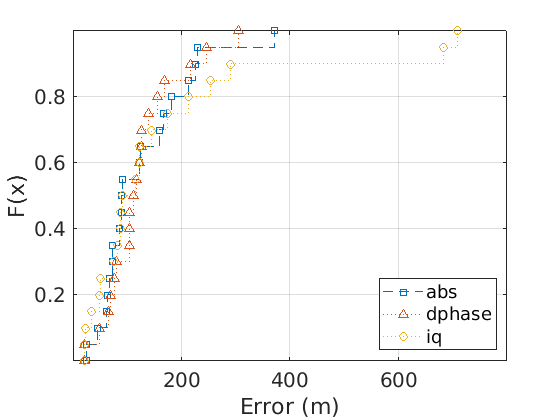

% Plotting
figure(); hold on; grid on;
stairs(abs_1_1_1.X_lls, abs_1_1_1.F_lls, '--s');
stairs(dphase_1_1_1.X_nlls, dphase_1_1_1.F_nlls, ':^');
stairs(iq_1_1_1.X_nlls, iq_1_1_1.F_nlls, ':o');
legend('abs','dphase', 'iq', 'Location','southeast');
xlabel('Error (m)');
xticks([200,400,600]); 
ylabel('F(x)');
yticks([0.2,0.4,0.6,0.8]);
box on; 
set(gca,'FontSize',15);
box on;

### Original - Mean - FOC - NLLS - Upsample

% No correction
load('/home/ygglc/desktop/phd/research/localization/core/localization-tdoa/matlab/sensys/madrid2/s6/mdphase_i1_c0_l0.mat')
dphase_1_0_0.lls = error_lls;
dphase_1_0_0.nlls = error_nlls;
[dphase_1_0_0.F_lls, dphase_1_0_0.X_lls] = ecdf(error_lls);
[dphase_1_0_0.F_nlls, dphase_1_0_0.X_nlls] = ecdf(error_nlls);

% Correction no LTE
load('/home/ygglc/desktop/phd/research/localization/core/localization-tdoa/matlab/sensys/madrid2/s6/mdphase_i1_c1_l0.mat')
dphase_1_1_0.lls = error_lls;
dphase_1_1_0.nlls = error_nlls;
[dphase_1_1_0.F_lls, dphase_1_1_0.X_lls] = ecdf(error_lls);
[dphase_1_1_0.F_nlls, dphase_1_1_0.X_nlls] = ecdf(error_nlls);

% Correction with LTE
load('/home/ygglc/desktop/phd/research/localization/core/localization-tdoa/matlab/sensys/madrid2/s6/mdphase_i1_c1_l1.mat')
dphase_1_1_1.lls = error_lls;
dphase_1_1_1.nlls = error_nlls;
[dphase_1_1_1.F_lls, dphase_1_1_1.X_lls] = ecdf(error_lls);
[dphase_1_1_1.F_nlls, dphase_1_1_1.X_nlls] = ecdf(error_nlls);

% Correction with LTE
load('/home/ygglc/desktop/phd/research/localization/core/localization-tdoa/matlab/sensys/madrid2/s6/mdphase_i5_c1_l1.mat')
dphase_10_1_1.lls = error_lls;
dphase_10_1_1.nlls = error_nlls;
[dphase_10_1_1.F_lls, dphase_10_1_1.X_lls] = ecdf(error_lls);
[dphase_10_1_1.F_nlls, dphase_10_1_1.X_nlls] = ecdf(error_nlls);

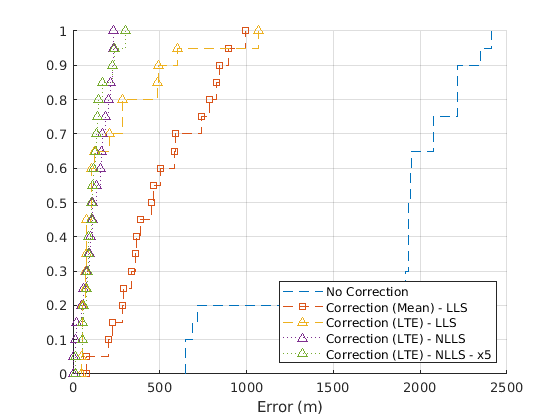

% Plotting
figure(); hold on; grid on;
stairs(dphase_1_0_0.X_lls, dphase_1_0_0.F_lls, '--');
stairs(dphase_1_1_0.X_lls, dphase_1_1_0.F_lls, '--s');
stairs(dphase_1_1_1.X_lls, dphase_1_1_1.F_lls, '--^');
stairs(dphase_1_1_1.X_nlls, dphase_1_1_1.F_nlls, ':^');
stairs(dphase_10_1_1.X_nlls, dphase_10_1_1.F_nlls, ':^');
legend('No Correction', 'Correction (Mean) - LLS', 'Correction (LTE) - LLS', 'Correction (LTE) - NLLS', 'Correction (LTE) - NLLS - x5', 'Location','southeast');
xlabel('Error (m)');

### Multipath/No Multipath

% 3 sensors
load('/home/ygglc/desktop/phd/research/localization/core/localization-tdoa/matlab/sensys/madrid2/s3/mdphase_i20_c1_l1.mat')
dphase_1_1_1.lls = error_lls;
dphase_1_1_1.nlls = error_nlls;
[dphase_1_1_1.F_lls, dphase_1_1_1.X_lls] = ecdf(error_lls);
[dphase_1_1_1.F_nlls, dphase_1_1_1.X_nlls] = ecdf(error_nlls);
offset = 0;
% offset = mean(lls(:,1:2),1) - torrespana(1:2);
nlls_corr = lls(:,1:2) - offset;
error_nlls_corr = distance(nlls_corr(:,1)',nlls_corr(:,2)',torrespana(1), torrespana(2), ell);
[no_mp_y, no_mp_x] = ecdf(error_nlls_corr);

% mpath
load('/home/ygglc/desktop/phd/research/localization/core/localization-tdoa/matlab/sensys/madrid2/s3/mdphase_i20_c1_l1_mp.mat')
dphase_1_1_1_mp.lls = error_lls;
dphase_1_1_1_mp.nlls = error_nlls;
[dphase_1_1_1_mp.F_lls, dphase_1_1_1_mp.X_lls] = ecdf(error_lls);
[dphase_1_1_1_mp.F_nlls, dphase_1_1_1_mp.X_nlls] = ecdf(error_nlls);
offset = 0;
% offset = mean(lls(:,1:2),1) - torrespana(1:2);
nlls_corr = lls(:,1:2) - offset;
error_nlls_corr = distance(nlls_corr(:,1)',nlls_corr(:,2)',torrespana(1), torrespana(2), ell);
[mp_y, mp_x] = ecdf(error_nlls_corr);

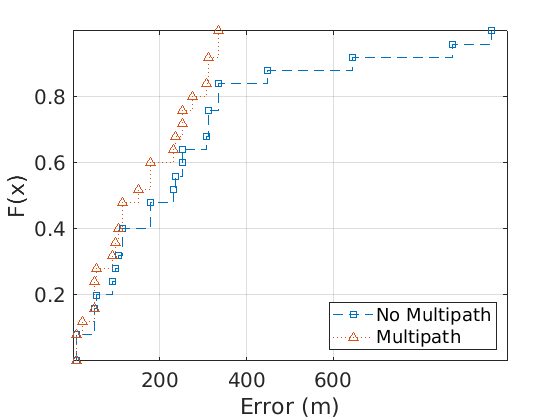

% Plotting
figure(); hold on; grid on;
stairs(no_mp_x, no_mp_y, '--s');
stairs(mp_x, mp_y, ':^');
legend('No Multipath', 'Multipath', 'Location','southeast');
xlabel('Error (m)');
xticks([200,400,600]); 
ylabel('F(x)');
yticks([0.2,0.4,0.6,0.8]);
box on; 
set(gca,'FontSize',15);
box on;

% 6 sensors
load('/home/ygglc/desktop/phd/research/localization/core/localization-tdoa/matlab/sensys/madrid2/s6/mdphase_i10_c1_l1.mat')
dphase_1_1_1.lls = error_lls;
dphase_1_1_1.nlls = error_nlls;
[dphase_1_1_1.F_lls, dphase_1_1_1.X_lls] = ecdf(error_lls);
[dphase_1_1_1.F_nlls, dphase_1_1_1.X_nlls] = ecdf(error_nlls);
offset = 0;
% offset = mean(nlls(:,1:2),1) - torrespana(1:2);
nlls_corr = nlls(:,1:2) - offset;
error_nlls_corr = distance(nlls_corr(:,1)',nlls_corr(:,2)',torrespana(1), torrespana(2), ell);
[no_mp_y, no_mp_x] = ecdf(error_nlls_corr);

% mpath
load('/home/ygglc/desktop/phd/research/localization/core/localization-tdoa/matlab/sensys/madrid2/s6/mdphase_i10_c1_l1_mp.mat')
dphase_1_1_1_mp.lls = error_lls;
dphase_1_1_1_mp.nlls = error_nlls;
[dphase_1_1_1_mp.F_lls, dphase_1_1_1_mp.X_lls] = ecdf(error_lls);
[dphase_1_1_1_mp.F_nlls, dphase_1_1_1_mp.X_nlls] = ecdf(error_nlls);
offset = 0;
% offset = mean(nlls(:,1:2),1) - torrespana(1:2);
nlls_corr = nlls(:,1:2) - offset;
error_nlls_corr = distance(nlls_corr(:,1)',nlls_corr(:,2)',torrespana(1), torrespana(2), ell);
[mp_y, mp_x] = ecdf(error_nlls_corr);

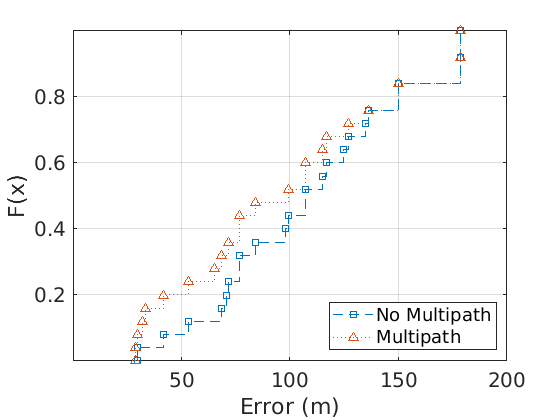

% Plotting
figure(); hold on; grid on;
stairs(no_mp_x, no_mp_y, '--s');
stairs(mp_x, mp_y, ':^');
legend('No Multipath', 'Multipath', 'Location','southeast');
xlabel('Error (m)');
xticks([50,100,150,200]); 
ylabel('F(x)');
yticks([0.2,0.4,0.6,0.8]);
box on; 
set(gca,'FontSize',15);
box on;

### Different Number of sensors

% 3 sensors
load('/home/ygglc/desktop/phd/research/localization/core/localization-tdoa/matlab/sensys/madrid2/s3/mdphase_i1_c1_l1.mat')
dphase_1_1_1.lls = error_lls;
dphase_1_1_1.nlls = error_nlls;
[dphase_1_1_1.F_lls, dphase_1_1_1.X_lls] = ecdf(error_lls);
[dphase_1_1_1.F_nlls, dphase_1_1_1.X_nlls] = ecdf(error_nlls);

% 4 sensors
load('/home/ygglc/desktop/phd/research/localization/core/localization-tdoa/matlab/sensys/madrid2/s4/mdphase_i1_c1_l1.mat')
dphase_1_1_1_4.lls = error_lls;
dphase_1_1_1_4.nlls = error_nlls;
[dphase_1_1_1_4.F_lls, dphase_1_1_1_4.X_lls] = ecdf(error_lls);
[dphase_1_1_1_4.F_nlls, dphase_1_1_1_4.X_nlls] = ecdf(error_nlls);
% offset = median(nlls(1:end-4,1:2),1) - torrespana(1:2);
offset = 0;
nlls_corr = lls(:,1:2) - offset;
error_nlls_corr = distance(nlls_corr(:,1)',nlls_corr(:,2)',torrespana(1), torrespana(2), ell);
[mp_4_y, mp_4_x] = ecdf(error_nlls_corr);

% 5 sensors
load('/home/ygglc/desktop/phd/research/localization/core/localization-tdoa/matlab/sensys/madrid2/s5/mdphase_i1_c1_l1.mat')
dphase_1_1_1_5.lls = error_lls;
dphase_1_1_1_5.nlls = error_nlls;
[dphase_1_1_1_5.F_lls, dphase_1_1_1_5.X_lls] = ecdf(error_lls);
[dphase_1_1_1_5.F_nlls, dphase_1_1_1_5.X_nlls] = ecdf(error_nlls);
% offset = mean(nlls(:,1:2),1) - torrespana(1:2);
offset = 0;
nlls_corr = nlls(:,1:2) - offset;
error_nlls_corr = distance(nlls_corr(:,1)',nlls_corr(:,2)',torrespana(1), torrespana(2), ell);
[mp_5_y, mp_5_x] = ecdf(error_nlls_corr);

% 6 sensors
load('/home/ygglc/desktop/phd/research/localization/core/localization-tdoa/matlab/sensys/madrid2/s6/mdphase_i1_c1_l1.mat')
dphase_1_1_1_6.lls = error_lls;
dphase_1_1_1_6.nlls = error_nlls;
[dphase_1_1_1_6.F_lls, dphase_1_1_1_6.X_lls] = ecdf(error_lls);
[dphase_1_1_1_6.F_nlls, dphase_1_1_1_6.X_nlls] = ecdf(error_nlls);
offset = mean(nlls(:,1:2),1) - torrespana(1:2);
nlls_corr = nlls(:,1:2) - offset;
error_nlls_corr = distance(nlls_corr(:,1)',nlls_corr(:,2)',torrespana(1), torrespana(2), ell);
[mp_6_y, mp_6_x] = ecdf(error_nlls_corr);

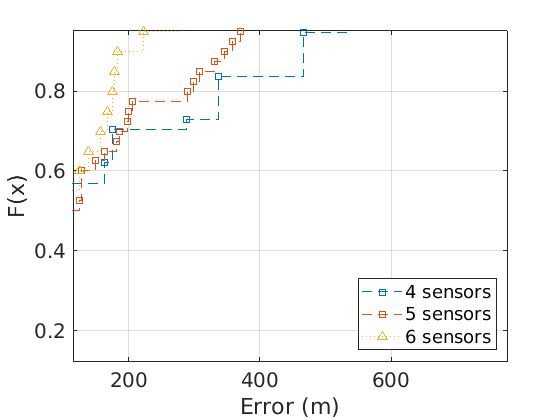

% Plotting
figure(); hold on; grid on;
stairs(dphase_1_1_1_4.X_nlls, dphase_1_1_1_4.F_nlls, '--s');
stairs(mp_5_x, mp_5_y, '--s');
stairs(mp_6_x, mp_6_y, ':^');
legend('4 sensors', '5 sensors', '6 sensors', 'Location','southeast');
xlabel('Error (m)');
xticks([200,400,600]); 
ylabel('F(x)');
yticks([0.2,0.4,0.6,0.8]);
box on; 
set(gca,'FontSize',15);
box on;